clear
load("modelo_lin.mat")

% evalc linmodel
model = longmod

model =
 
  A = 
                   u           w           q
   u         -0.5961      0.8011      -0.871
   w         -0.7454      -7.581       15.72
   q           1.042      -7.427      -15.85
   theta           0           0           1
   Ze       -0.05377      0.9986           0
   omega       135.8       7.315           0
 
               theta          Ze       omega
   u          -9.791   5.053e-05     0.01263
   w         -0.5272  -0.0009384           0
   q               0  -8.001e-16    -0.01318
   theta           0           0           0
   Ze            -17           0           0
   omega           0    -0.08268      -5.919
 
  B = 
          elevator  throttle
   u        0.4681         0
   w        -2.711         0
   q        -134.1         0
   theta         0         0
   Ze            0         0
   omega         0      2506
 
  C = 
                   u           w           q
   V          0.9986     0.05377           0
   alpha   -0.003163     0.05874        


longmod.A

ans =    -0.5961    0.8011   -0.8710   -9.7915    0.0001    0.0126
   -0.7454   -7.5810   15.7162   -0.5272   -0.0009         0
    1.0417   -7.4269  -15.8518         0   -0.0000   -0.0132
         0         0    1.0000         0         0         0
   -0.0538    0.9986         0  -17.0000         0         0
  135.8430    7.3147         0         0   -0.0827   -5.9187


longmod.B

ans = 	1.0e+03 *

    0.0005         0
   -0.0027         0
   -0.1341         0
         0         0
         0         0
         0    2.5061


longmod.C

ans =     0.9986    0.0538         0         0         0         0
   -0.0032    0.0587         0         0         0         0
         0         0    1.0000         0         0         0
         0         0         0    1.0000         0         0
         0         0         0         0   -1.0000         0
   -0.5961    0.8011    0.0431         0    0.0001    0.0126
   -0.7454   -7.5810   -1.2592         0   -0.0009         0


longmod.D

ans =          0         0
         0         0
         0         0
         0         0
         0         0
    0.4681         0
   -2.7109         0



%% Numerical errors
model.A(abs(model.A)<1e-10)=0;
model.B(abs(model.B)<1e-10)=0;
model.C(abs(model.C)<1e-10)=0;
model.D(abs(model.D)<1e-10)=0;



model.A

ans =    -0.5961    0.8011   -0.8710   -9.7915    0.0001    0.0126
   -0.7454   -7.5810   15.7162   -0.5272   -0.0009         0
    1.0417   -7.4269  -15.8518         0         0   -0.0132
         0         0    1.0000         0         0         0
   -0.0538    0.9986         0  -17.0000         0         0
  135.8430    7.3147         0         0   -0.0827   -5.9187


model.B

ans = 	1.0e+03 *

    0.0005         0
   -0.0027         0
   -0.1341         0
         0         0
         0         0
         0    2.5061


model.C

ans =     0.9986    0.0538         0         0         0         0
   -0.0032    0.0587         0         0         0         0
         0         0    1.0000         0         0         0
         0         0         0    1.0000         0         0
         0         0         0         0   -1.0000         0
   -0.5961    0.8011    0.0431         0    0.0001    0.0126
   -0.7454   -7.5810   -1.2592         0   -0.0009         0


model.D

ans =          0         0
         0         0
         0         0
         0         0
         0         0
    0.4681         0
   -2.7109         0



g1 = tf(model(4,1));
% g2 = q/elevator
g2 = tf(model(3,1));
G = [g1; g2]

G =
 
  From input "elevator" to output...
                                            
           -134.1 s^4 - 1869 s^3 - 6807 s^2 
                                            
                          - 2268 s - 0.07966
                                            
   theta:  ---------------------------------
                                            
           s^6 + 29.95 s^5 + 392.9 s^4      
                                            
                   + 1609 s^3 + 637.7 s^2   
                                            
                           + 642 s + 0.07726
                                            
 
                                            
       -134.1 s^5 - 1869 s^4 - 6807 s^3     
                                            
               - 2268 s^2 - 0.07966 s       
                                            
                                 + 1.752e-18
                                            
   q:  -------------------------------------
          


kd = -0.5;
clc
damp(g2)

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -1.20e-04                 1.00e+00       1.20e-04         8.31e+03    
 -1.60e-01 + 6.40e-01i     2.42e-01       6.60e-01         6.26e+00    
 -1.60e-01 - 6.40e-01i     2.42e-01       6.60e-01         6.26e+00    
 -6.20e+00                 1.00e+00       6.20e+00         1.61e-01    
 -1.17e+01 + 1.00e+01i     7.60e-01       1.54e+01         8.54e-02    
 -1.17e+01 - 1.00e+01i     7.60e-01       1.54e+01         8.54e-02    



damp(feedback(g2,kd))

                                                                       
         Pole              Damping       Frequency      Time Constant  
                                       (rad/seconds)      (seconds)    
                                                                       
 -1.20e-04                 1.00e+00       1.20e-04         8.31e+03    
 -1.75e-01 + 3.33e-01i     4.65e-01       3.76e-01         5.72e+00    
 -1.75e-01 - 3.33e-01i     4.65e-01       3.76e-01         5.72e+00    
 -6.21e+00                 1.00e+00       6.21e+00         1.61e-01    
 -8.98e+00                 1.00e+00       8.98e+00         1.11e-01    
 -8.14e+01                 1.00e+00       8.14e+01         1.23e-02    


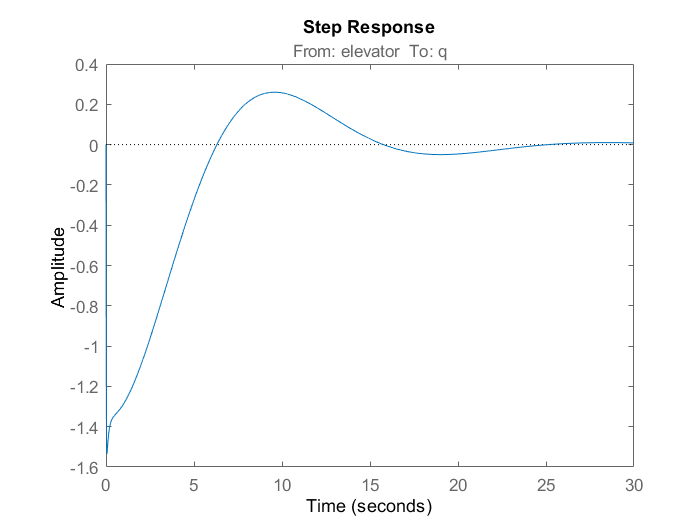


figure()
step(feedback(g2,kd))

KD=-0.1:-0.1:-1.5

KD =    -0.1000   -0.2000   -0.3000   -0.4000   -0.5000   -0.6000   -0.7000   -0.8000   -0.9000   -1.0000   -1.1000   -1.2000   -1.3000   -1.4000   -1.5000


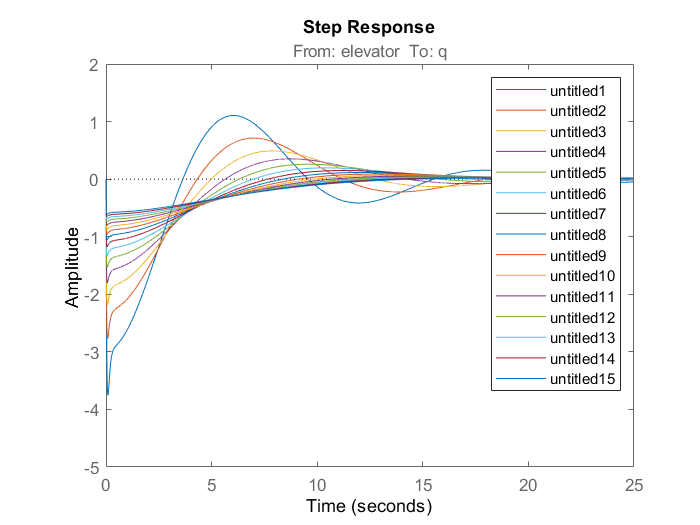

figure()
hold on
for i=1:length(KD)
    step(feedback(g2,KD(i)))
end
hold off
legend
axis([0 25 -5 2])


g2fb=feedback(g2,KD(5))

g2fb =
 
  From input "elevator" to output "q":
                                            
  -134.1 s^5 - 1869 s^4 - 6807 s^3          
                                            
          - 2268 s^2 - 0.07966 s + 1.752e-18
                                            
  ------------------------------------------
                                            
  s^6 + 96.98 s^5 + 1327 s^4 + 5013 s^3     
                                            
                + 1772 s^2 + 642 s + 0.07726
                                            
 
Continuous-time transfer function.



s=tf('s')

s =
 
  s
 
Continuous-time transfer function.




ki=-0.1:-0.3:-3

ki =    -0.1000   -0.4000   -0.7000   -1.0000   -1.3000   -1.6000   -1.9000   -2.2000   -2.5000   -2.8000


kp=-0.1:-0.3:-3

kp =    -0.1000   -0.4000   -0.7000   -1.0000   -1.3000   -1.6000   -1.9000   -2.2000   -2.5000   -2.8000


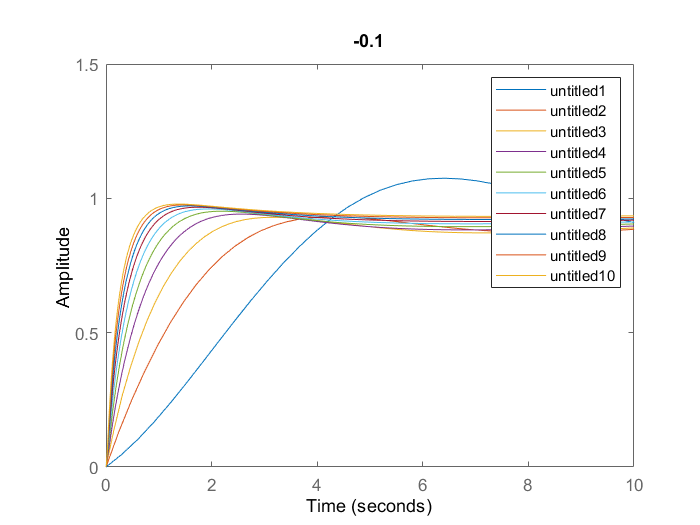

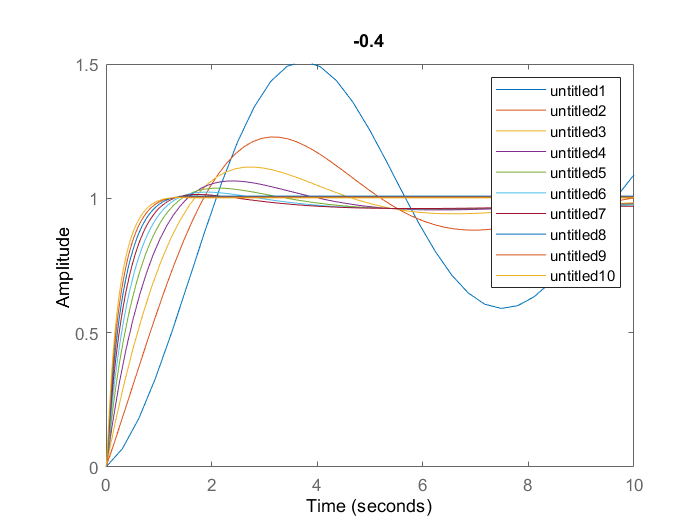

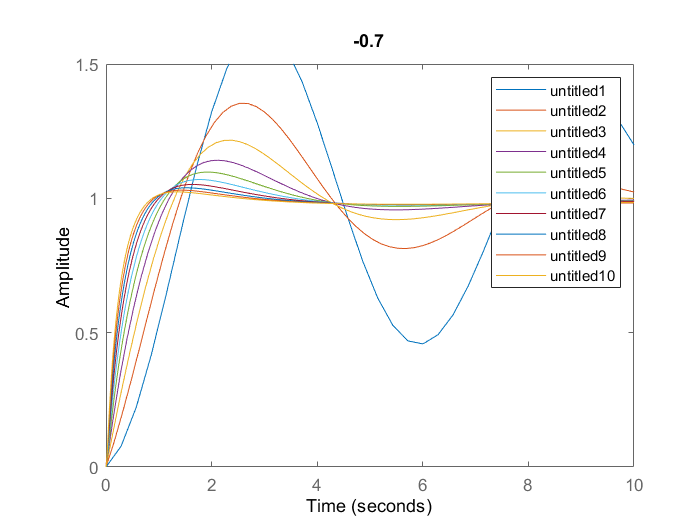

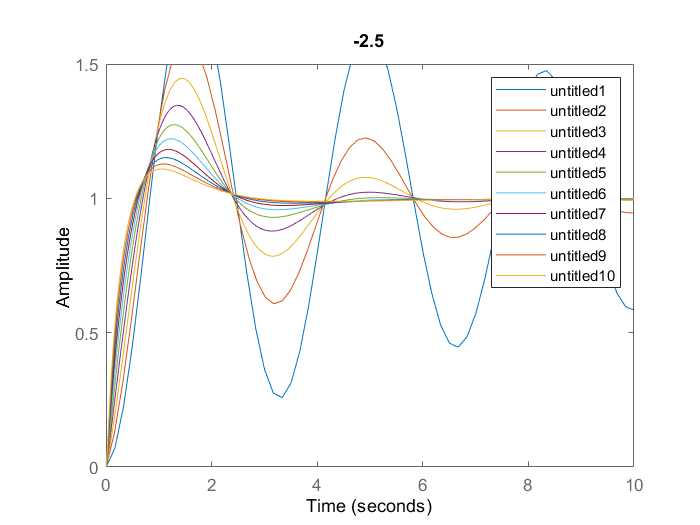

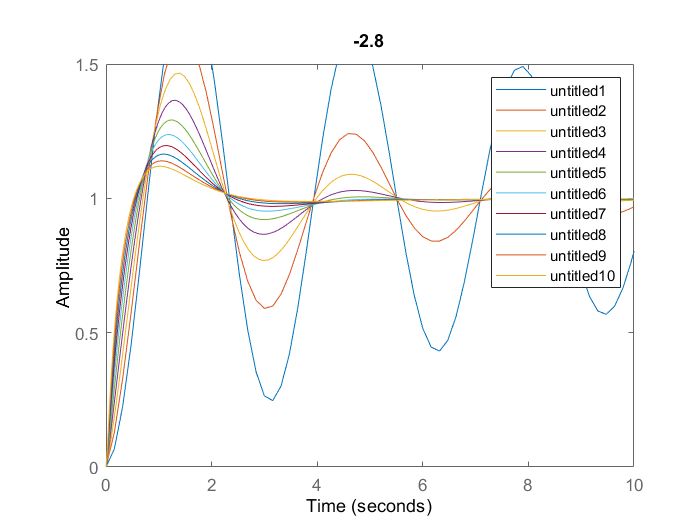


for j=1:length(ki)
    figure
    hold on
    for k=1:length(kp)
        C=ki(j)/s+kp(k);
        step(feedback(C*g2fb/s,1))
    end
    hold off
    legend
    title(ki(j))
    axis([0 10 0 1.5])
end

ki=-0.1

ki = -0.1000

kp=-0.2

kp = -0.2000

kd=-0.5

kd = -0.5000


ki=-3

ki = -3

kp=-0.75

kp = -0.7500

kd=-0.5

kd = -0.5000



g2fb=feedback(g2,kd)

g2fb =
 
  From input "elevator" to output "q":
                                            
  -134.1 s^5 - 1869 s^4 - 6807 s^3          
                                            
          - 2268 s^2 - 0.07966 s + 1.752e-18
                                            
  ------------------------------------------
                                            
  s^6 + 96.98 s^5 + 1327 s^4 + 5013 s^3     
                                            
                + 1772 s^2 + 642 s + 0.07726
                                            
 
Continuous-time transfer function.




C=ki/s+kp

C =
 
  -0.75 s - 3
  -----------
       s
 
Continuous-time transfer function.



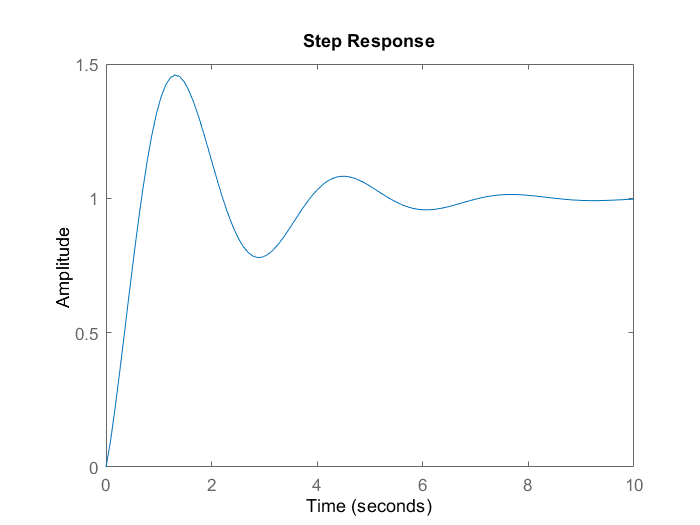

step(feedback(C*g2fb/s,1))